#                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        Harmonic Oscillator

## Basic Case

One mass, one spring, single DOF, no damping, no external force

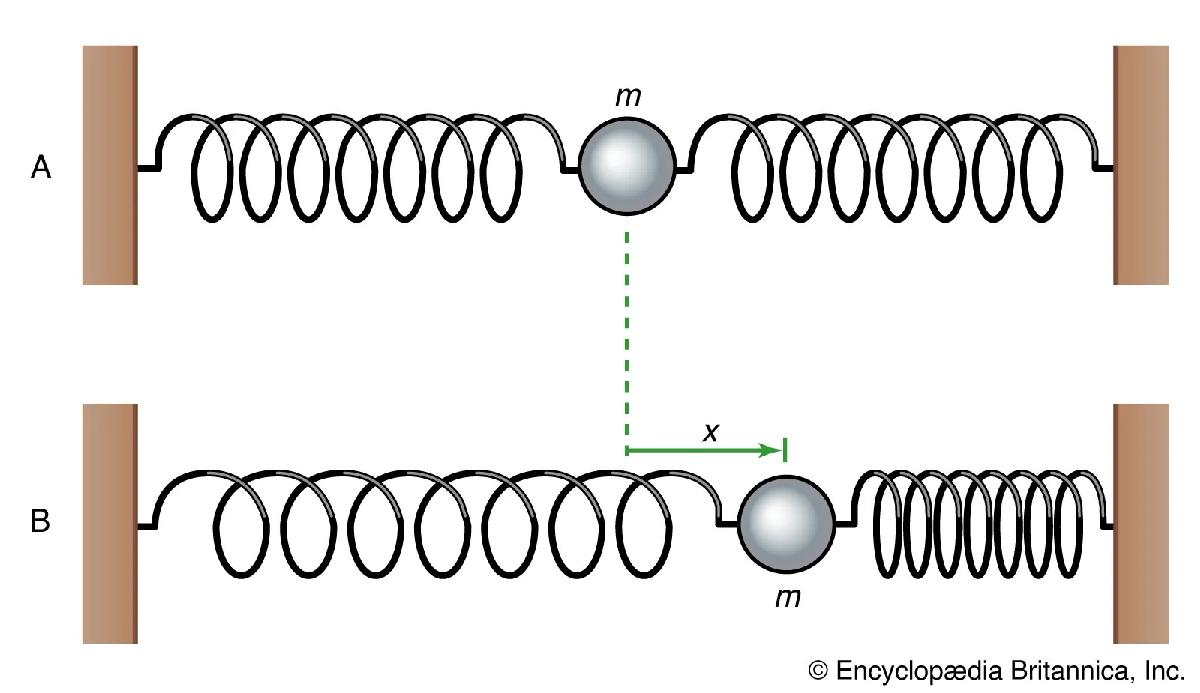

The equation of motion for this sistem is:

##                         
$$m \ddot x + kx = 0$$


With the solution:

##                 
$$x(t) = A \cdot sin(\omega t + \phi)$$


where A and $\phi$ are derived from initial conditions, and $\omega = \sqrt \frac{k}{m}$

This analitical solution can be plotted immidiately:

a = 1; % initial conditions
phi = 0; %initial conditions
f = 1; %[Hz] the frequency is determined by ration between k and m
omega = 2*pi*f;

t_an = linspace(0,10,1001);
x_an = a * sin(omega*t_an + phi);

figure
plot(t_an,x_an)
xlabel('time [sec]')
ylabel('sin(\omega t)')
title ('Basic Harmonic oscillation')
hold on
grid on

## Numerical Integration

There of course no neet to solve this numerically. But it would be useful to start checking numerical simulation on the simple, analitical case.

System parameters:

Normalized mass: m = 1 

for f=1[Hz] -> $\omega = 2 \cdot \pi \cdot f = \sqrt \frac {k}{m} ; m=1; f =1 \Rightarrow (2\cdot\pi)^2 = k$

m = 1;
k = 4*pi*pi; %so that f=1[hz]

Initial conditions:

x0 = 0

$\dot x = \omega \cdot sin(\omega t)$ for f=1[Hz] => $\omega = 2\pi$

x0 = 0; % sin
xdot0 = 2*pi; % cos

the equations would be:


$$\ddot x = -\frac{k}{m}\cdot x
$$


and x and its first derivative are determined by integration.

### The simplest and the most basic integration is the simple summation:


$$y_{i+1} = y_i + \dot y_i \cdot \Delta t$$


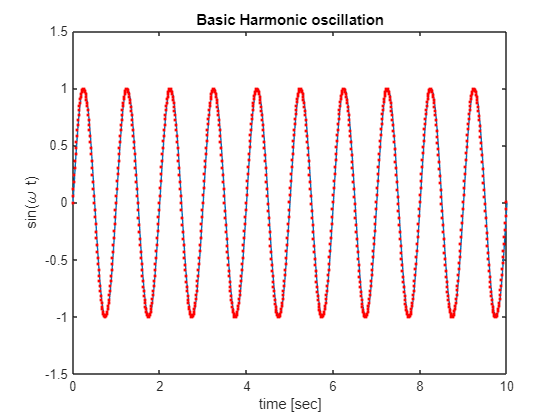

dt = 0.01; %integration interval [sec]
%initialization
t_num(1) = 0;
x_num(1) = x0;
xdot(1) = xdot0;
%iterative solution
for ind = 1:1000
    xdotdot(ind) = -k/m*x_num(ind);

    t_num(ind+1) = t_num(ind) + dt;
    xdot(ind+1) = xdot(ind) + xdotdot(ind) * dt;
    x_num(ind+1) = x_num(ind) + xdot(ind+1) * dt; %the first derivative is already calculated
end

plot(t_num,x_num,'r.')

The simplest method gives good enough results for the simple case, given integration interval small enough. As the complexity of the problem progresses, we will need to employ smarter solutions for numeric integration.

### Average error

The error between the numerical calculation and the theoretical one.

err = x_num - x_an;
err2 = err.*err;
sumerr = sum(err2)

sumerr = 0.0180

sumerr2n = sumerr/length(t_num)

sumerr2n = 1.7956e-05

## Damped

One mass, one spring, single DOF, damping proportional to velocity, no external force

The equation of motion for this sistem is:

##                         
$$m \ddot x + b \dot x + kx = 0$$


With the solution:

##                 
$$x(t) = A \cdot e^{-t/\tau} \cdot  sin(\omega t + \phi)$$


where A and $\phi$ are derived from initial conditions, and $\omega = \sqrt {\frac{k}{m}-\left(\frac{b}{2m}\right)^2$ and $\tau = \frac{b}{2m}$

This analitical solution can be plotted immidiately. Keeping the same prameters as before, only adding damping.

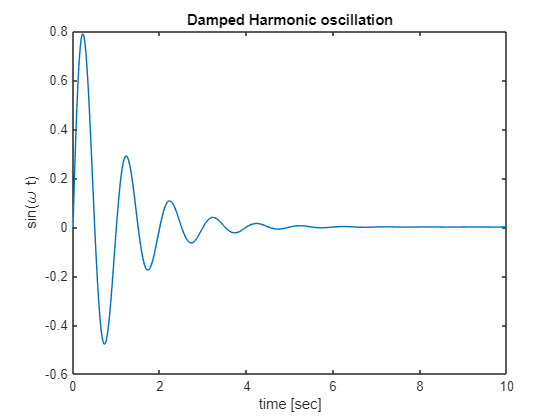

a = 1; % initial conditions
phi = 0; %initial conditions
f = 1; %[Hz] the frequency is determined by ration between k and m
omega = 2*pi*f;
tau = 1;

t_an = linspace(0,10,1001);
x_an = a * exp(-t_an/tau) .* sin(omega*t_an + phi);

figure
plot(t_an,x_an)
xlabel('time [sec]')
ylabel('sin(\omega t)')
title ('Damped Harmonic oscillation')
hold on

grid on

In terms of dynamic sistem the equation of motion is written:

##                      
$$\ddot x + 2\zeta \omega_n \dot x + \omega_n^2 = 0$$


For such system the critical damping is $\zeta = 0.7$

It was previously chosen for f=1[Hz] -> $f = 1[=Hz]   \Rightarrow \omega = 2 \pi$ and m =1 therefore $\tau = \frac{2\zeta \cdot 2\pi}{2 \cdot m} = 2\pi \zeta$

We can use the slider tool to see the change in the system behaiviour as we change the damping coefficient